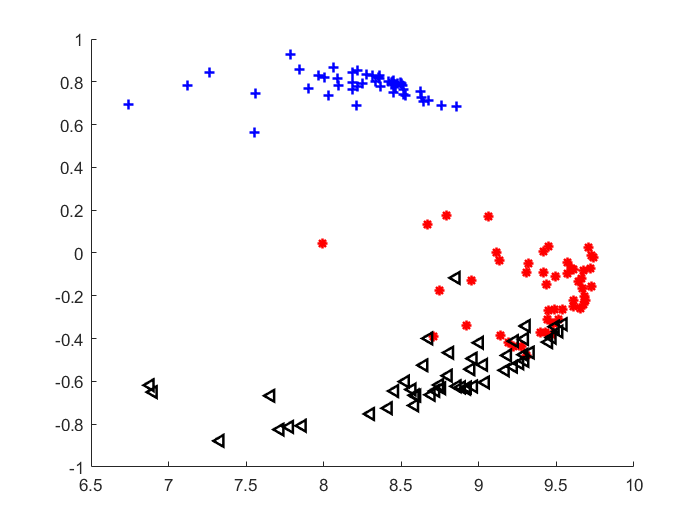

clear
clc
%  each row is a data point
Data = iris_dataset';
X = zscore(Data);

% Compute the Gaussian Kernel matrix with parameter sigma
% Do not usee the following iteration
% for i = 1:len  
%     for j = 1:len
%         K1(i,j) = exp(-sum((X(i,:)-X(j,:)).^2)); 
%     end 
% end
sigma = 32;
sX = (sum(X.^2, 2)); 
K2 = exp(bsxfun(@minus,bsxfun(@minus,2*X*X', sX),sX')/sigma); 

% if you have test sample B, then the following matrix should be compute
% for projection
% sB = (sum(B.^2, 2)); 
% K_test = exp(bsxfun(@minus,bsxfun(@minus,2*X*B', sX), sB')/sigma); 

% in this sample, K_test = K2. The test data is the same as the training
% data.
[A,D] = eig(K2);
d = diag(D);
[~,inx] = sort(d,'descend');
dim = 2;
X_dim = K2*A(:,inx(1:dim))*1/sqrt(150)*sqrt(D(inx(1:dim),inx(1:dim)));
X_dim = X_dim';
figure
hold on
plot(X_dim(1,1:50),X_dim(2,1:50),'b+','LineWidth',1.5);
plot(X_dim(1,51:100),X_dim(2,51:100),'r*','LineWidth',1.5);
plot(X_dim(1,101:150),X_dim(2,101:150),'k<','LineWidth',1.5);